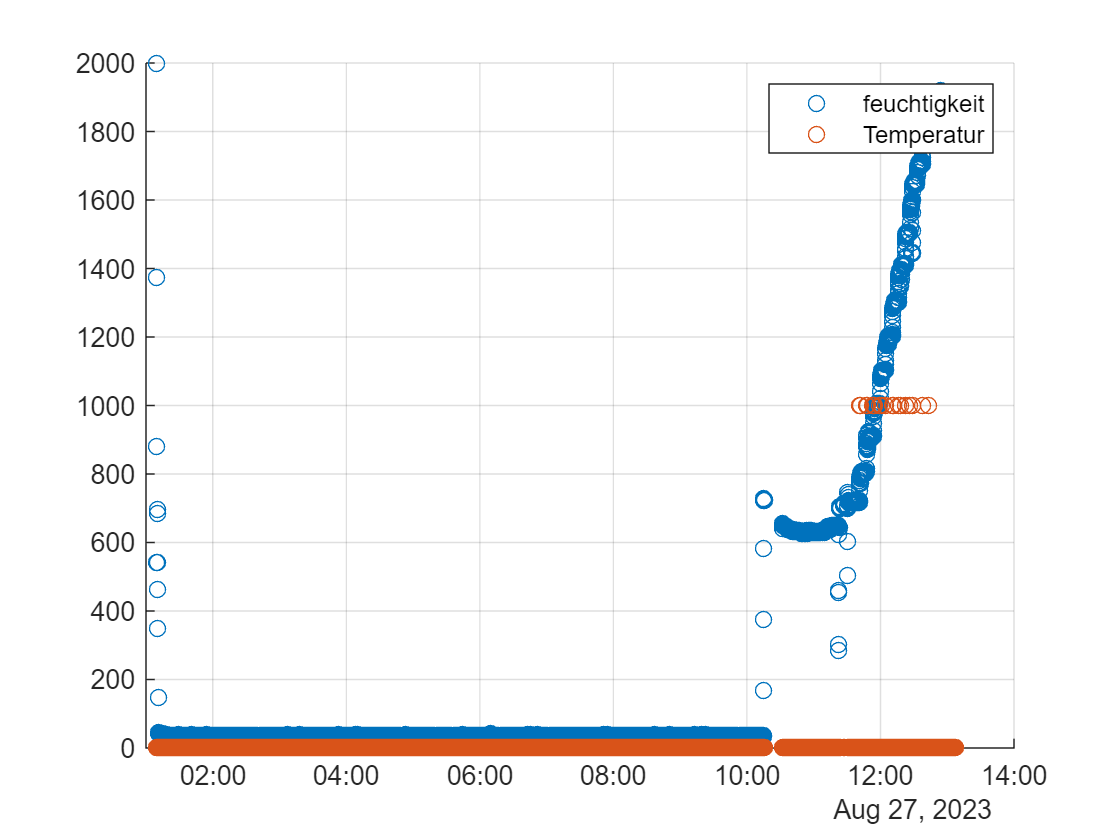

a = readtable("D:\data_log.txt",'Delimiter',';');
a.datetime = datetime(a.datetime,'InputFormat','(yyyy,MM,dd,HH,mm,ss)');
a = table2timetable(a);
a.Properties.VariableNames;

scatter(a.datetime ,a.EC)
hold on
scatter(a.datetime ,a.Pumpe_5*1000)
legend("feuchtigkeit","Temperatur")
grid on